**This code calculate the surface temperature distribution and permitted ice coverage in specified condition. **

clear;
addpath(genpath('..\function'))
filename='params.xlsx';
data=readmatrix(filename,'Range','A2:G5');

Mr=data(1,1);
Lr=data(1,2);
e=0;
T_ratio=1;
gamma=deg2rad(0);
F=0.09;
precess=0;
a=149598023e3*sqrt(Lr); % axis equivalent to Earth

G=6.67e-11;     % gravitational constant
L0=3.828e26;     % Sun Luminosity
M0=1.98855e30;      % Sun mass
L=L0*Lr;    % Stellar Luminosity
M=M0*Mr;   % Stellar mass
b=a*sqrt(1-e^2);
T_orb=sqrt(a^3*4*pi^2/(G*M));       % revolution period
T_rot=T_orb/T_ratio;     % rotation period
w=2*pi/T_rot;    % spin velocity
dt=T_rot/200;    % time step
nyear=20;     % integral time (year)
J=2*pi*a*b/T_orb;    % revolution angular momentum

% calculate time sequence of seasonal angle and longitude of substellar point
kappa=0;     % initial seasonal angle
slon=pi;    % initial longitude of substellar point
r=caculate_r(a,e,kappa);
% Euler's forward 
[E,~]=Kepler(J,a,e,kappa);
kappa(2)=kappa(1)+dt*E;
slon(2)=slon(1)-dt*(w-E);
while slon(2)<0 || slon(2)>2*pi
    if slon(2)<0
        slon(2)=slon(2)+2*pi;
    else
        slon(2)=slon(2)-2*pi;
    end
end
% Central Difference
while kappa(end)<kappa(1)+2*nyear*pi
    n=size(kappa,2);
    [E,r(n)]=Kepler(J,a,e,kappa(n));
    kappa(n+1)=kappa(n-1)+2*dt*E;
    slon(n+1)=slon(n-1)-2*dt*(w-E);
    while slon(n+1)<0 || slon(n+1)>2*pi
        if slon(n+1)<0
            slon(n+1)=slon(n+1)+2*pi;
        else
            slon(n+1)=slon(n+1)-2*pi;
        end
    end
end
r(n+1)=caculate_r(a,e,kappa(end));

% plot(rad2deg(slon)-180,'LineWidth',2)
% xlim([0 600])
% xticks(0:150:600)
% ylim([-180 180])
% yticks(-180:90:180)
% yticklabels({'180\circW','90\circW','0\circ','90\circE','180\circE'})
% xlabel('Time / dt')
% ylabel('Longitude of subsolar point / \circ')
% grid on

% calculate incident stellar flux of each point
% set parameters
n1=10;     % latitude grid point
n2=20;     % longitude grid point
n3=n+1;     % number of time steps
slat=asin(cos(kappa-precess).*sin(gamma));     % latitude of substellar plot
lat=linspace(-pi/2,pi/2,n1);
lon=linspace(0,2*pi,n2);
flux=zeros(n1,n2,n3);        %(lat,lon,time)
for i=1:n1
    for j=1:n2
        for k=1:n3
            flux(i,j,k)=caculate_flux(lat(i),slat(k),lon(j)-slon(k),r(k),L);
        end
    end
end

% plot(1:n3,squeeze(flux(6,11,:)))
% plot(1:n3,slon)
% plot(rad2deg(slat),'LineWidth',2)
% xlim([0 200])
% xticks(0:50:200)
% ylim([-45 45])
% yticks(-45:22.5:45)
% yticklabels({'45\circS','22.5\circS','0\circ','22.5\circN','45\circN'})
% xlabel('Time / dt')
% ylabel('Latitude of subsolar point / \circ')
% grid on


% params
% clearvars -except flux F lat lon ...
%     dt T_rot L b ...
%     n1 n2 n3 nyear ...
%     z
absorp=1-0.2;
%soil layers
Kt=2.9;
rcp=2.02e6;     %rock
nz=35;
z=zeros(nz+1,1);
z0=sqrt(Kt*dt/rcp);
for i=1:(nz+1)
    z(i)=z0*(exp((i-1)/5)-1)/(exp(3)-1);
end
dz=zeros(nz,1);
for i=1:nz
    if i<nz
        dz(i)=(z(i+2)-z(i))/2;
    else
        dz(nz)=z(i+1)-z(i);
    end
end
%initial temperature
T=zeros(n1,n2,n3,nz+1);
T(:,:,1,:)=100;

% solution of soil heat conduction equation
m=rcp/dt;
%caculate coef matrix A
A=zeros(nz+1);  
c2=-Kt/(z(2)-z(1));
A(1,2)=c2;
for j=2:nz
    c1=Kt/(dz(j-1)*(z(j)-z(j-1)));
    c3=Kt/(dz(j-1)*(z(j+1)-z(j)));
    c2=-(m+c1+c3);
    A(j,j-1:j+1)=[c1,c2,c3];
end
c1=Kt/(dz(nz)*(z(nz+1)-z(nz)));
c2=-(m+c1);
A(nz+1,nz:nz+1)=[c1,c2];

for nlat=1:n1
    for nlon=1:n2
        for i=2:n3
            %time-related terms in A
            c1=OLR(T(nlat,nlon,i-1,1),1)+Kt/(z(2)-z(1));
            A(1,1)=c1;
            %caculate B
            rad_in=flux(nlat,nlon,i);
            b0=absorp*rad_in-OLR(T(nlat,nlon,i-1,1),0)+OLR(T(nlat,nlon,i-1,1),1)*T(nlat,nlon,i-1,1);
            temp=squeeze(T(nlat,nlon,i-1,2:nz));
            b_m=cat(1,b0,-m*temp,-m*squeeze(T(nlat,nlon,i-1,nz+1))-F/dz(nz));
            %solve AX=B
            T(nlat,nlon,i,:)= tridiagonal(A,b_m)';
        end
    end
end
T_sur=T(:,:,:,1);

% Count number of grid with temperature less than the threshold
low=140; % threshold
narea=0;
rarea=0;
rarea_grid=caculate_rarea(lat,lon);     % array: grid area
for nlat=1:n1
    for nlon=1:n2
        flag=1;
        for i=(n3-201):n3
            if T_sur(nlat,nlon,i)>low
                flag=0;
                break
            end
        end 
        if flag==1
            narea=narea+1;
            rarea=rarea+rarea_grid(nlat,nlon);
        end
    end
end
rarea=rarea/(4*pi);
disp('Surface ice coverage: ')

Surface ice coverage: 


disp(rarea)

    0.4942



% clearvars -except T_sur lat lon rarea narea

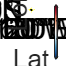

% Surface temperature distribution
figure
m_proj('robinson','lat',[-90 90],'lon',[-180 180]);
temp=T_sur(:,:,end);
colormap([m_colmap('diverging')]);  
[~,h]=m_contourf(rad2deg(lon)-180,rad2deg(lat),temp,7);
set(h,'Color','none');
clim([100 380]);
c=colorbar;
cbarrow
hold on;
v=[140 140];
m_contour(rad2deg(lon)-180,rad2deg(lat),temp,v,'LineWidth',2,'Linecolor','y');
m_grid;
xlabel('Lat')
ylabel('Lon')
hold off;